# Sink Mobility in WSN by Random Way point Model


close all
clc
clear
warning off
addpath(genpath(cd))
% create directory to store the results

d=num2str(clock);
d(isspace(d))=[];
if ~exist('Results','dir')
    mkdir('Results')
end
mkdir(['Results/',d])


## Initialize the network paramteres and other variables

N=100;  % number of N in the network
Tr =87.7; % Transmission range in meter
no_clusters=10;
rounds=1000; % number of simulation time
E0=1;  % node's initial energy
NiniE = E0*ones(N,1);   % initial energy of every Node
packtsize = 512; % bytes
% define the x.y coordinates of the deployed area
X=[1,100];
Y=[1,100]; 
sinknode = [X(2)/2 Y(2)];  % sink node locations
% randomly deployment of N in the area
Nodepos = [(X(2)-X(1)).*rand(N,1)+X(1),(Y(2)-Y(1)).*rand(N,1)+Y(1)]; 

up=N;
low=1;
% initialization
initEnergy=0.5;                 %Initial Energy
nodeTable.energy=initEnergy.*ones(1,N)';
nodeTable.packetsize = packtsize*ones(1,N);
nodeTable.nodeID=[1:N]';
nodeTable.dead=zeros(1,N)';
nodeTable.Alive=ones(1,N)';
nodeTable.status=repmat('S',N,1);  % assign status to each node
nodeTable_BFO=nodeTable;
packets_delivered=[];
packets_delivered1=[];
packets_delivered_CS=[];
packets_delivered1_CS=[];


% calculate the distance between each node
for ii=1:N
    for jj=1:N
        dist(ii,jj) = sqrt((Nodepos(ii,1)-Nodepos(jj,1))^2+(Nodepos(ii,2)-Nodepos(jj,2))^2);
        if dist(ii,jj)>Tr
            connect(ii,jj)=0;
        else
            connect(ii,jj)=1;
        end
    end
end

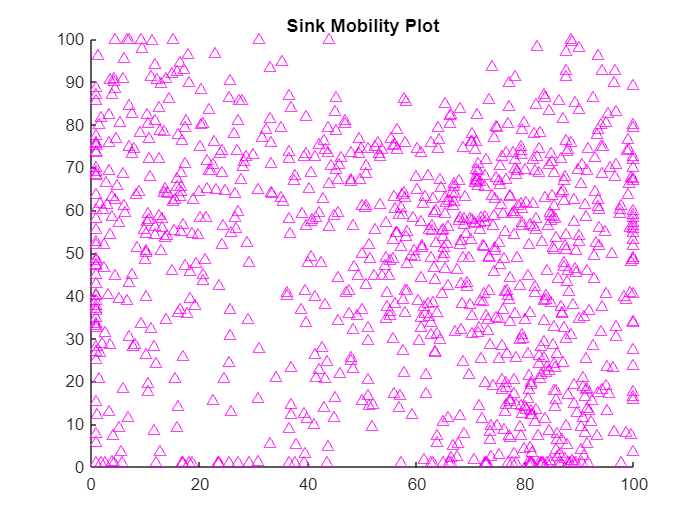

Msink = [X(2)/2 Y(2)/2];
for ii=1:rounds  % simulation time
    
    direction = unifrnd(0,2*pi);% random direction
    Velocity = unifrnd(2,16); % random velocity
    Msink(ii+1,1) = Msink(ii,1)+Velocity*cos(direction); % update the x corodinate
    Msink(ii+1,2) = Msink(ii,2)+Velocity*sin(direction); % update the y coordinate
    if (Msink(ii+1,1)  > X(2))

        new_direction = 180 - direction;
        Msink(ii+1,1) = X(2);
        Msink(ii+1,2)= Msink(ii+1,2) + (diff([Msink(ii,1) Msink(ii+1,1)]))*tand(new_direction);
    end
    if (Msink(ii+1,1) < X(1))
        new_direction = 180 - direction;
        Msink(ii+1,1) = X(1);
        Msink(ii+1,2)= Msink(ii+1,2) + (diff([Msink(ii,1) Msink(ii+1,1)]))*tand(new_direction);
    end
    if (Msink(ii+1,2)  > Y(2))

        new_direction = -direction;
        Msink(ii+1,2) = Y(2);
        Msink(ii+1,1) = Msink(ii+1,1) + (diff([Msink(ii,2) Msink(ii+1,2)]))*tand(new_direction);
    end
    if (Msink(ii+1,2)  < Y(1))

        new_direction = -direction;
        Msink(ii+1,2) = Y(1);
        Msink(ii+1,1) = Msink(ii+1,1) + (diff([Msink(ii,2) Msink(ii+1,2)]))*tand(new_direction);
    end

end
figure
scatter(Msink(:,1),Msink(:,2),'magenta','^')
title('Sink Mobility Plot')